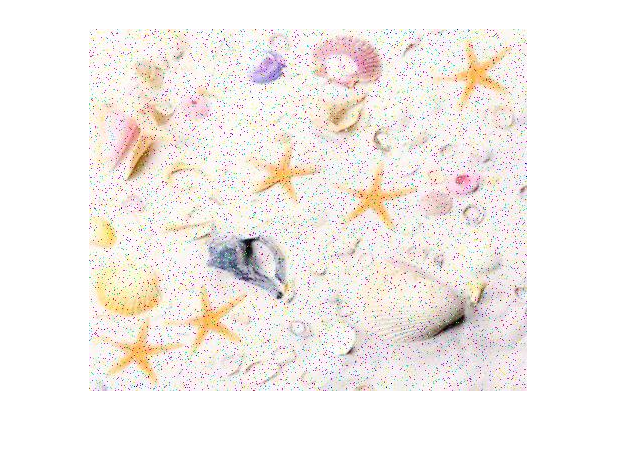

im = imread("images\starfish.jpg");
imshow(im)

% sp = imnoise(im, 'salt & pepper', 0.5);
% sp = imnoise(im, 'salt & pepper', 0.25);
sp = im;

noisyPixels = 84721

noisyPixels = 100531

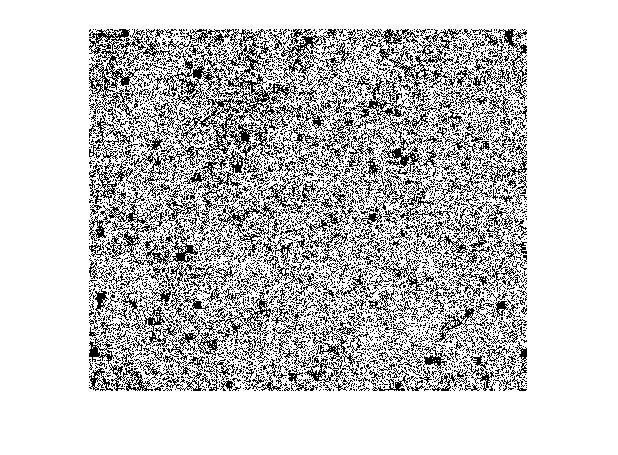

noisyPixels = 98364

denoised = sp;
% denoised = DenoiseSP(sp);
denoised2 = DenoiseIsolated(denoised);

noisyPixels = 41940

noisyPixels = 49617

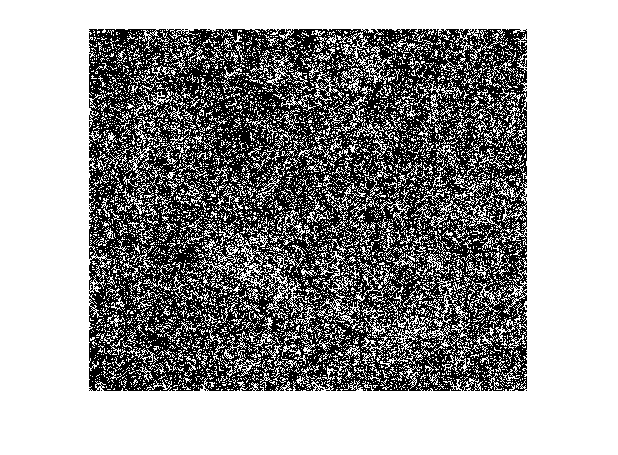

noisyPixels = 48185

denoised2 = DenoiseIsolated(denoised2);

noisyPixels = 30517

noisyPixels = 38969

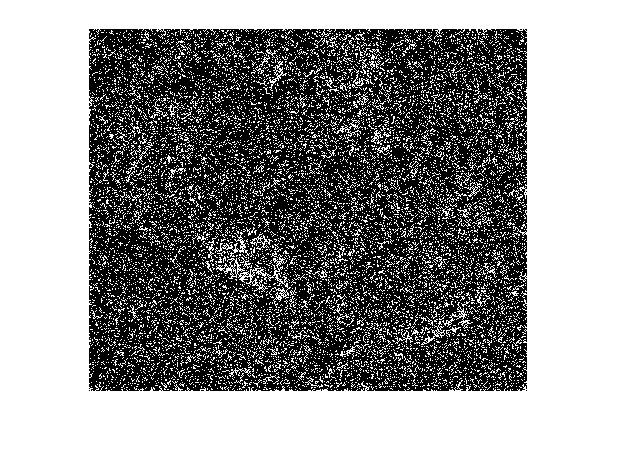

noisyPixels = 33005

denoised2 = DenoiseIsolated(denoised2);

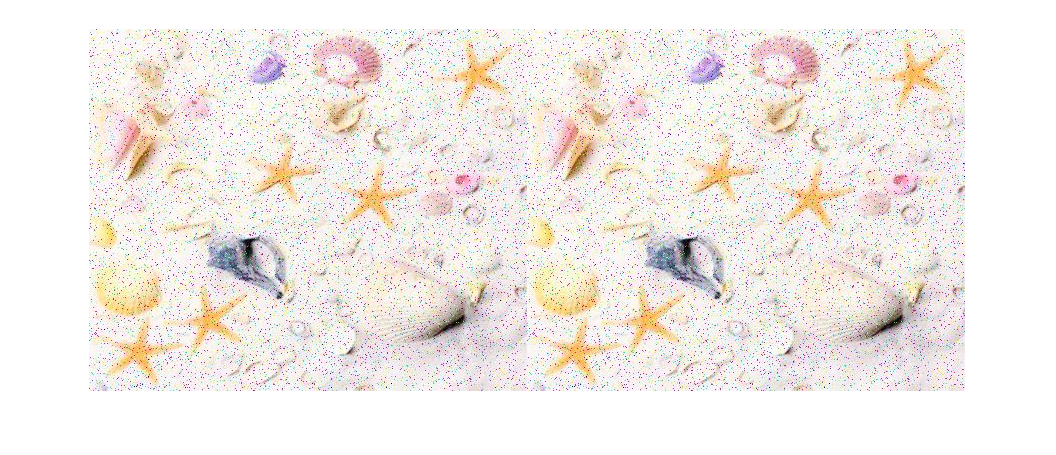

imshowpair(im, sp, 'montage')

imshowpair(sp, denoised, 'montage')

imshowpair(im, denoised, 'montage')

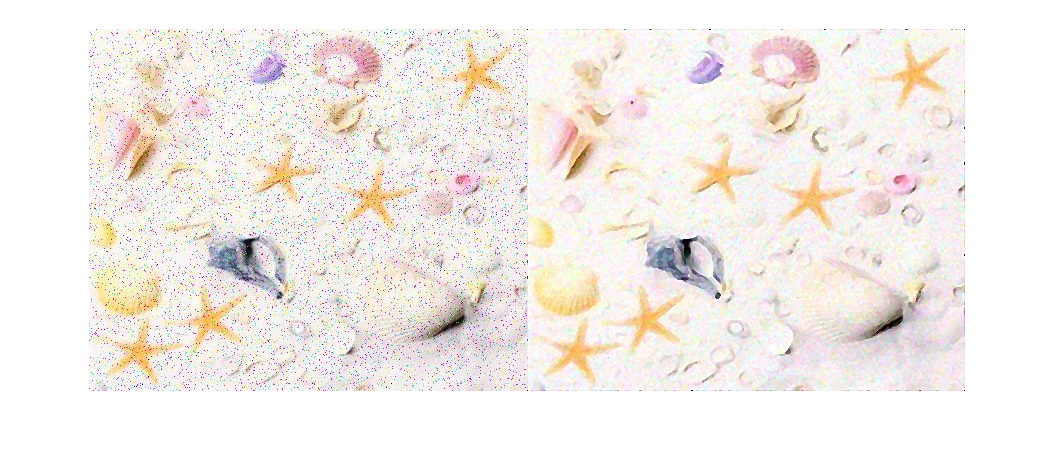

imshowpair(denoised, denoised2, 'montage')

function [ch1, ch2, ch3] = CountImpulsePixels(im)
[ch1, ch2, ch3] = imsplit(im);
ch1 = length(find(ch1 == 0 | ch1 == 255));
ch2 = length(find(ch2 == 0 | ch2 == 255));
ch3 = length(find(ch3 == 0 | ch3 == 255));
end


function imP = DenoiseSP(im)
dims = ndims(im);

if (dims == 2)
    imP = DenoiseSP2D(im);
elseif (dims == 3)
    imP = DenoiseSP3D(im);
else
    error("Unsupported number of dimensions. Expected a 2D or 3D array.");
end
% Little effect on low noise, tops off extra noisy ims.
% imP = imsharpen(imP);
% imP = medfilt3(imP);
% imP = imsharpen(imP);
end


function imP = DenoiseSP2D(im)
imP = im;
for i = 1:2 % Run twice
    noise = (imP == 0 | imP == 255);
    
    % Create a median filtered copy of im.
    filtered = medfilt2(imP, [3 3]);
    
    % Swap noisy pixels with filtered pixels.
    denoised = imP;
    denoised(noise) = filtered(noise);
    
    imP = denoised;
end

%     Consideration...
%     Conditionally determine filter size based on numel(noise).
end


function imP = DenoiseSP3D(im)
% Separate image channels.
[ch1, ch2, ch3] = imsplit(im);

% Denoise channels individually.
dnCh1 = DenoiseSP2D(ch1);
dnCh2 = DenoiseSP2D(ch2);
dnCh3 = DenoiseSP2D(ch3);

% Concatenate channels to create noise free image.
imP = cat(3, dnCh1, dnCh2, dnCh3);
end


function imP = DenoiseIsolated(im)
dims = ndims(im);

if (dims == 2)
    imP = DenoiseIsolated2D(im);
elseif (dims == 3)
    imP = DenoiseIsolated3D(im);
else
    error("Unsupported number of dimensions. Expected a 2D or 3D array.");
end
imP = imsharpen(imP);
end


function imP = DenoiseIsolated3D(im)
% Separate image channels.
[ch1, ch2, ch3] = imsplit(im);

% Denoise channels individually.
dnCh1 = DenoiseIsolated2D(ch1);
dnCh2 = DenoiseIsolated2D(ch2);
dnCh3 = DenoiseIsolated2D(ch3);

% Concatenate channels to create noise free image.
imP = cat(3, dnCh1, dnCh2, dnCh3);
end



function denoised = DenoiseIsolated2D(im)
% Isolate speckle and S&P noise
filtered = medfilt2(im, [3 3]);
% filtered = conv2(double(im), ones(3)/9, 'same');
imLnStd = log(std2(im));
diff = abs(double(im) - double(filtered));
noise = (diff > imLnStd);
imshow(noise)
noisyPixels = sum(noise(:))
% noisePercentage = (100/numel(im)) * noisePixels
noise = (noise == 1);

% Swap noisy pixels for filtered ones
denoised = im;
denoised(noise) = filtered(noise);
end